# Taller de Tecnomatemática: Primera Práctica

### Ejercicio 2:

## **Datos:**

% Datos
x = linspace(0,3,50)'; 
y0 = 2; y3 = 5;

% Red 1 capa oculta
N_hidden = 10;
W1 = randn(N_hidden,1); 
b1 = randn(N_hidden,1);
W2 = randn(1,N_hidden); 
b2 = randn;

% Parámetros de entrenamiento
nu = 0.01; 
iter = 200;
lambda = 0.01;  % peso de suavidad

L_hist = zeros(iter,1);

### Preparación del GIF:

gif_filename = 'gift_ej1_entrega1.gif';

## Proceso de entrenamiento:

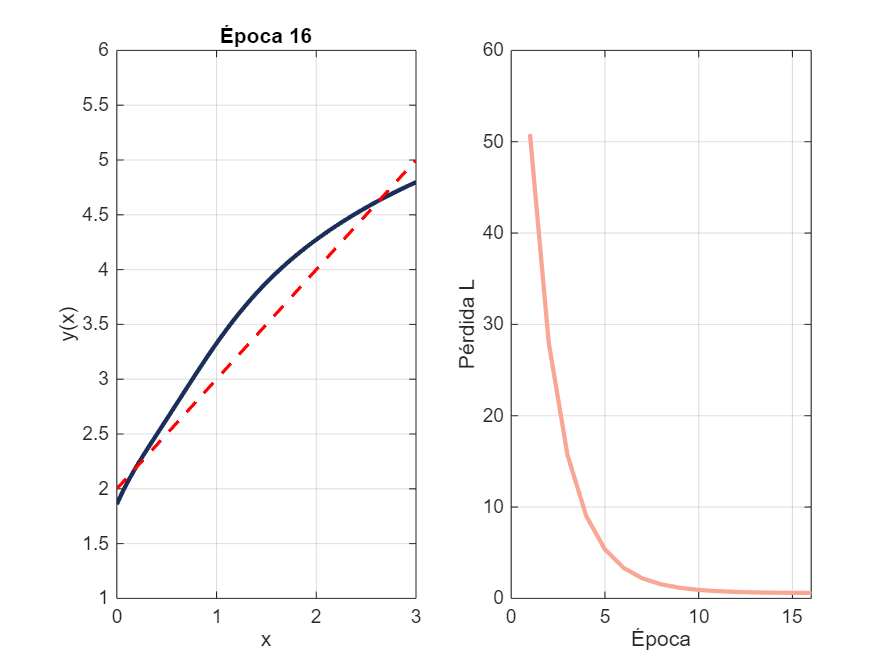

figure;
for i = 1:iter

    % Función sumadora
    Z = W1*x' + b1*ones(1,length(x));

    % Función de activación
    A = tanh(Z);                        
    Y_pred = W2*A + b2;                 

    sigma_double = -2*tanh(Z).*(1 - tanh(Z).^2);  
    Ypp = W2 * (sigma_double .* (W1.^2));        

    % Función de Pérdida
    L = lambda*sum(Ypp.^2) + (Y_pred(1)-y0)^2 + (Y_pred(end)-y3)^2;
    L_hist(i) = L; % Guardar historia

    if i > 1 % Parar cuando deje de mejorar la función
        if L_hist(i) > L_hist(i-1) 
            break
        end
    end

    % Gradientes
    % W2
    grad_W2 = 2*lambda * (Ypp * (sigma_double .* (W1.^2))') + ...
              2*(Y_pred(1)-y0)*A(:,1)' + 2*(Y_pred(end)-y3)*A(:,end)'; 

    % b2
    grad_b2 = 2*(Y_pred(1)-y0) + 2*(Y_pred(end)-y3);  % escalar

    % W1 
    grad_W1 = 2*lambda * sum( Ypp .* (W2' .* 2 .* W1 .* sigma_double), 2 );

    % b1
    sigma_triple = -2*(1 - tanh(Z).^2).^2 - 4*tanh(Z).^2 .* (1 - tanh(Z).^2); 
    grad_b1 = 2*lambda * sum( Ypp .* (W2' .* (W1.^2 .* sigma_triple)), 2 );   

    % Actualización de pesos
    W2 = W2 - nu*grad_W2;
    b2 = b2 - nu*grad_b2;
    W1 = W1 - nu*grad_W1;
    b1 = b1 - nu*grad_b1;

    % Visualización:
    clf;

    % Subplot 1:
    subplot(1, 2, 1)
    plot(x,Y_pred,'b','Color', [0.10 0.18 0.35], 'LineWidth',2); hold on
    plot([0 3],[y0 y3],'r--','LineWidth',1.5)
    ylim([1 6]); grid on
    xlabel('x'); ylabel('y(x)');
    title(['Época ',num2str(i)]);

     % Subplot 2: pérdida
    subplot(1, 2, 2)
    plot(L_hist(1:i), 'Color', [0.98 0.65 0.58], 'LineWidth', 2)
    xlabel('Época')
    ylabel('Pérdida L')
    grid on;
    
    drawnow;

    % Guardar GIF
    if mod(i,5) == 0   % cada 5 épocas
        frame = getframe(gcf);
        im = frame2im(frame);
        [imind,cm] = rgb2ind(im,256);
        if i == 5
            imwrite(imind, cm, gif_filename, 'gif', 'Loopcount', inf, 'DelayTime', 0.1);
        else
            imwrite(imind, cm, gif_filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.1);
        end
    end
end

Resultados finales:

fprintf('Pérdida final L = %.6f\n', L);

Pérdida final L = 0.603323
